# Classification Trees

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Load the pump features from `pumpFeatures.`

T = readtable("./data/pumpFeatures.csv");

Partition into training and testing

rng(0)
cv = cvpartition(size(T, 1), "HoldOut", 0.3);
dataTrain = T(cv.training, :)

dataTrain = 700×85 table
    wMotor_mean    wMotor_std    wMotor_fftPeakIdx    wMotor_skewness    wMotor_kurtosis    wMotor_peak2peak    wMotor_peak2rms    wMotor_rms    wMotor_mad    wMotor_csRange    wMotor_pLow    wMotor_pMid    wMotor_pHigh    wMotor_pKur    iMotor_mean    iMotor_std    iMotor_fftPeakIdx    iMotor_skewness    iMotor_kurtosis    iMotor_peak2peak    iMotor_peak2rms    iMotor_rms    iMotor_mad    iMotor_csRange    iMotor_pLow    iMotor_pMid    iMotor_pHigh    iMotor_pKur    qIn_mean  

dataTest = T(cv.test, :)

dataTest = 300×85 table
    wMotor_mean    wMotor_std    wMotor_fftPeakIdx    wMotor_skewness    wMotor_kurtosis    wMotor_peak2peak    wMotor_peak2rms    wMotor_rms    wMotor_mad    wMotor_csRange    wMotor_pLow    wMotor_pMid    wMotor_pHigh    wMotor_pKur    iMotor_mean    iMotor_std    iMotor_fftPeakIdx    iMotor_skewness    iMotor_kurtosis    iMotor_peak2peak    iMotor_peak2rms    iMotor_rms    iMotor_mad    iMotor_csRange    iMotor_pLow    iMotor_pMid    iMotor_pHigh    iMotor_pKur    qIn_mean   

## Task 1

To construct a classification tree, use the `fitctree` function with a table as input and specify the name of the response variable.

`treeModel` `=` `fitctree``(``tableData``,``...`

    `"``ResponseVariable``"``)``;`

You can visualize the decision tree with the `view` function.

`view``(``treeModel``,``"mode"``,``"graph"``)`

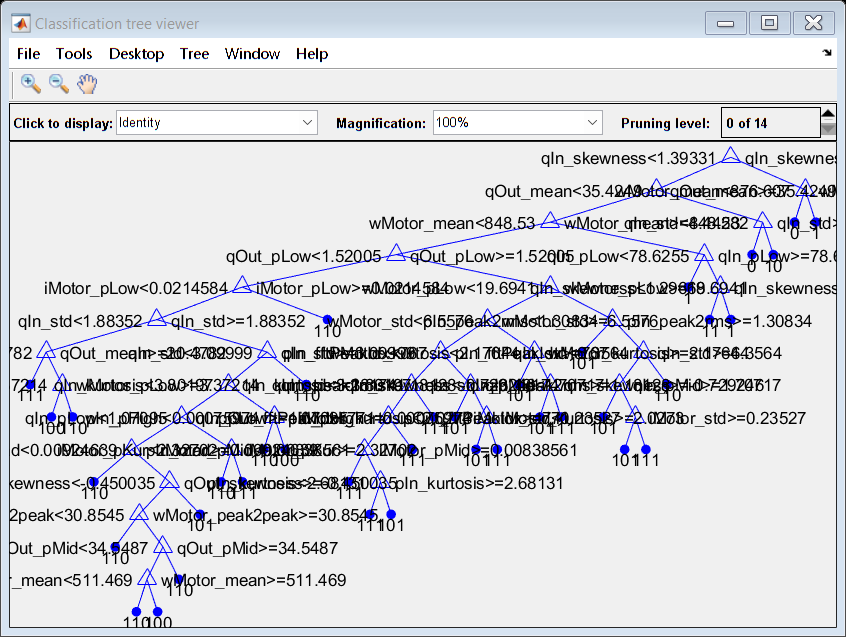

mdl = fitctree(dataTrain, "faultCode");
view(mdl, "mode", "graph")

Evaluate model

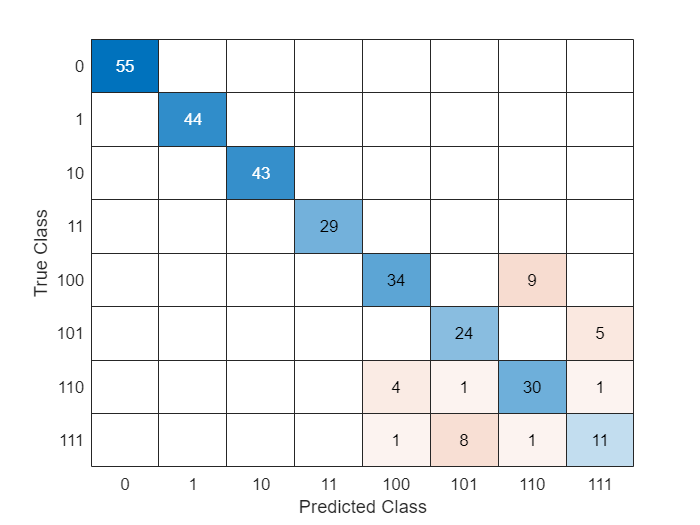

Training Error: 0.02
Loss: 0.11724


evalModel(dataTest, mdl)

## Task 2

You can change the level of branching of the classification tree using the `prune` function.

`prunedTreeModel` `=` `prune``(``treeModel``,``...`

    `"Level"``,``integer``)``;`

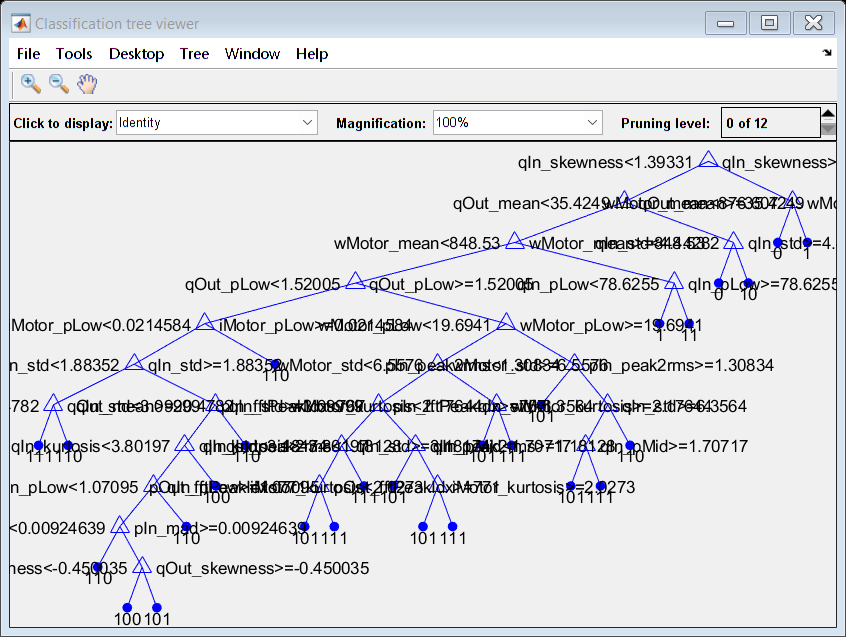

mdlPruned = prune(mdl, "Level", 2);
view(mdlPruned, "mode", "graph")

Evaluate model

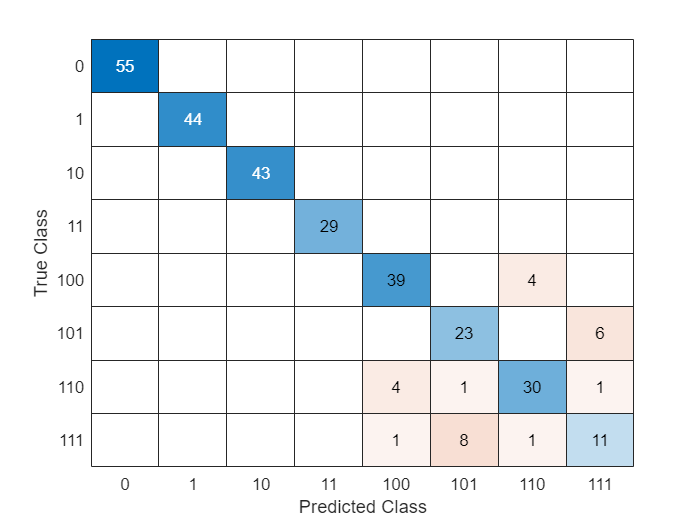

Training Error: 0.032857
Loss: 0.10614


evalModel(dataTest, mdlPruned)

Do not edit. This function is used to evaluate a model by displaying the confusion chart, training error, and test loss.

function evalModel(dataTest, mdl)
    confusionchart(dataTest.faultCode, predict(mdl, dataTest))
    disp("Training Error: " + resubLoss(mdl))
    disp("Loss: " + loss(mdl, dataTest))
end